clear all
close all
clc

currentFolder='//Users/hannahfarnsworth/Dropbox (HMS)/hyperdata';
cd(currentFolder)

load CompiledPhysio_final.mat

%Get baselinefood
ID=tempMasterData.Properties.RowNames %I keep reusing ID in my code so I just keep loading this

ID = 261×1 cell array
    {'H1' }
    {'H2' }
    {'H3' }
    {'H4' }
    {'H5' }
    {'H6' }
    {'H7' }
    {'H8' }
    {'H9' }
    {'H10'}
    {'H11'}
    {'H12'}
    {'H13'}
    {'H14'}
    {'H15'}
    {'H16'}
    {'H17'}
    {'H18'}
    {'H19'}
    {'H20'}
    {'H21'}
    {'H22'}
    {'H23'}
    {'H24'}
    {'H25'}
    {'H26'}
    {'H27'}
    {'H28'}
    {'H29'}
    {'H30'}


IDa=cell2table(ID)

IDa = 261×1 table
      ID   
    _______

    {'H1' }
    {'H2' }
    {'H3' }
    {'H4' }
    {'H5' }
    {'H6' }
    {'H7' }
    {'H8' }
    {'H9' }
    {'H10'}
    {'H11'}
    {'H12'}
    {'H13'}
    {'H14'}
    {'H15'}
    {'H16'}



%this code is just how I got baselinefood deltaFood
[h]=table2array(deltaFoodData(:,["D3Habituation" "D2Habituation" "D1Habituation" "D0Treatment"]));
h_t=transpose(h);
baselineFood_t=nanmean(h_t);
baselineFood=transpose(baselineFood_t);
baselineFoodTable=array2table(baselineFood);
baselineFoodTable.Properties.RowNames=ID  

baselineFoodTable = 261×1 table
           baselineFood
           ____________

    H1           4.3   
    H2           3.9   
    H3           2.7   
    H4           3.6   
    H5           3.9   
    H6           3.6   
    H7           4.8   
    H8           NaN   
    H9           4.5   
    H10          4.5   
    H11       4.4333   
    H12          4.8   
    H13          6.1   
    H14       6.3667   
    H15          4.5   
    H16          4.5   



baselinemean=nanmean(baselineFood)

baselinemean =        4.0254


Dev=nanstd(baselineFood)

Dev =        1.0116


PosThreeDev=baselinemean+(3*(Dev))

PosThreeDev =        7.0602


NegThreeDev=baselinemean-(3*(Dev))

NegThreeDev =        0.9905


%Find Outliers in Baseline Days 

%Find Mice that ate over 3std in baseline days
[Outliers, ~] = find(baselineFood>=7.0602);
%do we have any errors, if so display the row names.
if ~isempty(Outliers)
    disp([{'potential errors in:'}; cat(1,ID(Outliers))])
else
    disp([{'no errors'}; {'congratulations!'}])
end

    'potential errors in:'
    'H145'
    'H223'




%Find mice that ate under 3std in baselinedays
[Outliers, ~] = find(baselineFood<=0.9905);
%do we have any errors, if so display the row names.
if ~isempty(Outliers)
    disp([{'potential errors in:'}; cat(1,ID(Outliers))])
else
    disp([{'no errors'}; {'congratulations!'}])
end

    'potential errors in:'
    'H89'
    'H214'



%FindOutliers in Intake Days

[foodintake]=table2array(deltaFoodData(:,["D1Treatment" "D2Treatment" "D3Treatment" "D4Treatment"]))

foodintake =           4.1          3.7          NaN          NaN
          4.9          4.4          NaN          NaN
          4.3          5.2          NaN          NaN
          4.9          5.4          NaN          NaN
          3.9          1.4          NaN          NaN
          3.9          4.8          NaN          NaN
          5.1          5.6          NaN          NaN
          NaN          NaN          NaN          NaN
          5.2          3.4          NaN          NaN
          5.1          4.4          NaN          NaN



%Find Mice that ate over 3std in intake days
[Outliers, ~] = find(foodintake>=7.0602);
%do we have any errors, if so display the row names.
if ~isempty(Outliers)
    disp([{'potential errors in:'}; cat(1,ID(Outliers))])
else
    disp([{'no errors'}; {'congratulations!'}])
end

    'potential errors in:'
    'H19'
    'H117'
    'H205'
    'H30'
    'H116'
    'H123'
    'H182'
    'H205'
    'H116'
    'H117'
    'H120'
    'H123'
    'H182'
    'H184'
    'H199'
    'H205'
    'H215'
    'H217'
    'H219'




%find mice that ate under 3st in intake days
[Outliers, ~] = find(foodintake<=0.9905);
%do we have any errors, if so display the row names.
if ~isempty(Outliers)
    disp([{'potential errors in:'}; cat(1,ID(Outliers))])
else
    disp([{'no errors'}; {'congratulations!'}])
end

    'potential errors in:'
    'H46'
    'H47'
    'H200'
    'H46'
    'H140'
    'H173'
    'H200'
    'H213'



Now Start Getting Data Ready for Graphing

%get Delta/Delta Food
consume_array=table2array(deltaFoodData(:,["D1Habituation" "D0Treatment" "D1Treatment" "D2Treatment" "D3Treatment"]))

consume_array =           NaN          4.3          4.1          3.7          NaN
          NaN          3.9          4.9          4.4          NaN
          NaN          2.7          4.3          5.2          NaN
          NaN          3.6          4.9          5.4          NaN
          NaN          3.9          3.9          1.4          NaN
          NaN          3.6          3.9          4.8          NaN
          NaN          4.8          5.1          5.6          NaN
          NaN          NaN          NaN          NaN          NaN
          NaN          4.5          5.2          3.4          NaN
          NaN          4.5          5.1          4.4          NaN


intakeI=consume_array-baselineFood;

%get percent normalized delta food
intakeII=100.*(intakeI./baselineFood);
format shortg

%make table and give appropriate tablenames
intake=array2table(intakeII)

intake = 261×5 table
    intakeII1    intakeII2    intakeII3    intakeII4    intakeII5
    _________    _________    _________    _________    _________

         NaN            0      -4.6512      -13.953        NaN   
         NaN            0       25.641       12.821        NaN   
         NaN            0       59.259       92.593        NaN   
         NaN            0       36.111           50        NaN   
         NaN            0            0      -64.103        NaN   
         NaN            0       8.3333       33.333        NaN   
         NaN            0         6.25       16.667        NaN   
         NaN          NaN          NaN          NaN        NaN   
         NaN            0       15.556      -24.444        NaN   
         NaN            0       13.333      -2.2222        NaN   
      3.7594    

intake.Properties.RowNames=ID

intake = 261×5 table
           intakeII1    intakeII2    intakeII3    intakeII4    intakeII5
           _________    _________    _________    _________    _________

    H1          NaN            0      -4.6512      -13.953        NaN   
    H2          NaN            0       25.641       12.821        NaN   
    H3          NaN            0       59.259       92.593        NaN   
    H4          NaN            0       36.111           50        NaN   
    H5          NaN            0            0      -64.103        NaN   
    H6          NaN            0       8.3333       33.333        NaN   
    H7          NaN            0         6.25       16.667        NaN   
    H8         

intake.Properties.VariableNames=["D1Habituation" "D0Treatment" "D1Treatment" "D2Treatment" "D3Treatment"]

intake = 261×5 table
           D1Habituation    D0Treatment    D1Treatment    D2Treatment    D3Treatment
           _____________    ___________    ___________    ___________    ___________

    H1            NaN               0        -4.6512        -13.953          NaN    
    H2            NaN               0         25.641         12.821          NaN    
    H3            NaN               0         59.259         92.593          NaN    
    H4            NaN               0         36.111             50          NaN    
    H5            NaN               0              0        -64.103          NaN    
    H6            NaN               0         8.3333         33.333          NaN    
    H7   

%Make percent normalized into a stack

%Add IDs to Intake Table
intakemasterII=[IDa intake];
intakemasterII.Properties.VariableNames =[{'Master_ID' '-1' '0' '1' '2' '3'}]

intakemasterII = 261×6 table
           Master_ID      -1          0          1          2        3 
           _________    _______    _______    _______    _______    ___

    H1      {'H1' }         NaN          0    -4.6512    -13.953    NaN
    H2      {'H2' }         NaN          0     25.641     12.821    NaN
    H3      {'H3' }         NaN          0     59.259     92.593    NaN
    H4      {'H4' }         NaN          0     36.111         50    NaN
    H5      {'H5' }         NaN          0          0    -64.103    NaN
    H6      {'H6' }         NaN          0     8.3333     33.333    NaN
    H7      {'H7' }         NaN          0       6.25     16.667    NaN


%Join MasterIDs and the Above Table
intakemasterI=join(masterID,intakemasterII)

intakemasterI = 261×25 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                                      ImportantNotes                        Var14      Var15         Var16         Var17       Var18    Var19      Var20         -1          0          1          2        3 
    _________    ________________    ________

intakemasterI.ImportantNotes=[]

intakemasterI = 261×24 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var15         Var16         Var17       Var18    Var19      Var20         -1          0          1          2        3 
    _________    ________________    ________    ________    ______________    

intakemasterI.Var15=[]

intakemasterI = 261×23 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var16         Var17       Var18    Var19      Var20         -1          0          1          2        3 
    _________    ________________    ________    ________    ______________    _____________________________

intakemasterI.Var16=[]

intakemasterI = 261×22 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var17       Var18    Var19      Var20         -1          0          1          2        3 
    _________    ________________    ________    ________    ______________    _____________________________    __________

intakemasterI.Var17=[]

intakemasterI = 261×21 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14    Var18    Var19      Var20         -1          0          1          2        3 
    _________    ________________    ________    ________    ______________    _____________________________    ______________    ______

intakemasterI.Var18=[]

intakemasterI = 261×20 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14    Var19      Var20         -1          0          1          2        3 
    _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    <s

intakemasterI.Var19=[]

intakemasterI = 261×19 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var20         -1          0          1          2        3 
    _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________

intakemasterI.Var20=[]

intakemasterI = 261×18 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      -1          0          1          2        3 
    _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _______________

intakemasterI.Var14=[]

intakemasterI = 261×17 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                    -1          0          1          2        3 
    _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________

intakemasterI.Properties.RowNames=ID

intakemasterI = 261×17 table
           Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                    -1          0          1          2        3 
           _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    ___________________________


%Stack Data
intakestack=stack(intakemasterI,{'-1' '0' '1' '2' '3'})

intakestack = 1305×14 table
            Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  -1_0_1_2_3_Indicator    -1_0_1_2_3
            _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ______

intakestack.Properties.VariableNames{'-1_0_1_2_3_Indicator'}='Day';
intakestack.Properties.VariableNames{'-1_0_1_2_3'}='PercentNormIntake'

intakestack = 1305×14 table
            Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Day    PercentNormIntake
            _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ________________

intakestack.Original_ID=[]

intakestack = 1305×13 table
            Master_ID    Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Day    PercentNormIntake
            _________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ______________________________________    ___    _______

%Figured out how to graph Outliers and Nonoutliers and Color them
%Was just playing around
c=gramm('x',intakestack.Day,'y',intakestack.PercentNormIntake,'color',intakestack.Master_ID~="H145" & intakestack.Master_ID~="H223" & intakestack.Master_ID~="H89" & intakestack.Master_ID~="H214" & intakestack.Master_ID~="H19"' ...
    & intakestack.Master_ID~="H117" & intakestack.Master_ID~="H19" & intakestack.Master_ID~="H117"& intakestack.Master_ID~="H205" & intakestack.Master_ID~="H30" & intakestack.Master_ID~="H116"& intakestack.Master_ID~="H123" & intakestack.Master_ID~="H182" & intakestack.Master_ID~="H205"& intakestack.Master_ID~="H120" ...
    & intakestack.Master_ID~="H184" & intakestack.Master_ID~="H199" & intakestack.Master_ID~="H215"& intakestack.Master_ID~="H217"& intakestack.Master_ID~="H219"& intakestack.Master_ID~="H46" & intakestack.Master_ID~="H47"& intakestack.Master_ID~="H200"& intakestack.Master_ID~="H213")

c =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


c.stat_boxplot();
c.set_names('x','Experimental Day','y',' FoodIntake')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c.set_title('Food Consumption: Outliers vs. Normal');
figure('Position',[100 100 2000 800]);
c.set_text_options('title_scaling',3,'label_scaling',2)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c.axe_property('YLim',[-100 150])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c.draw

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


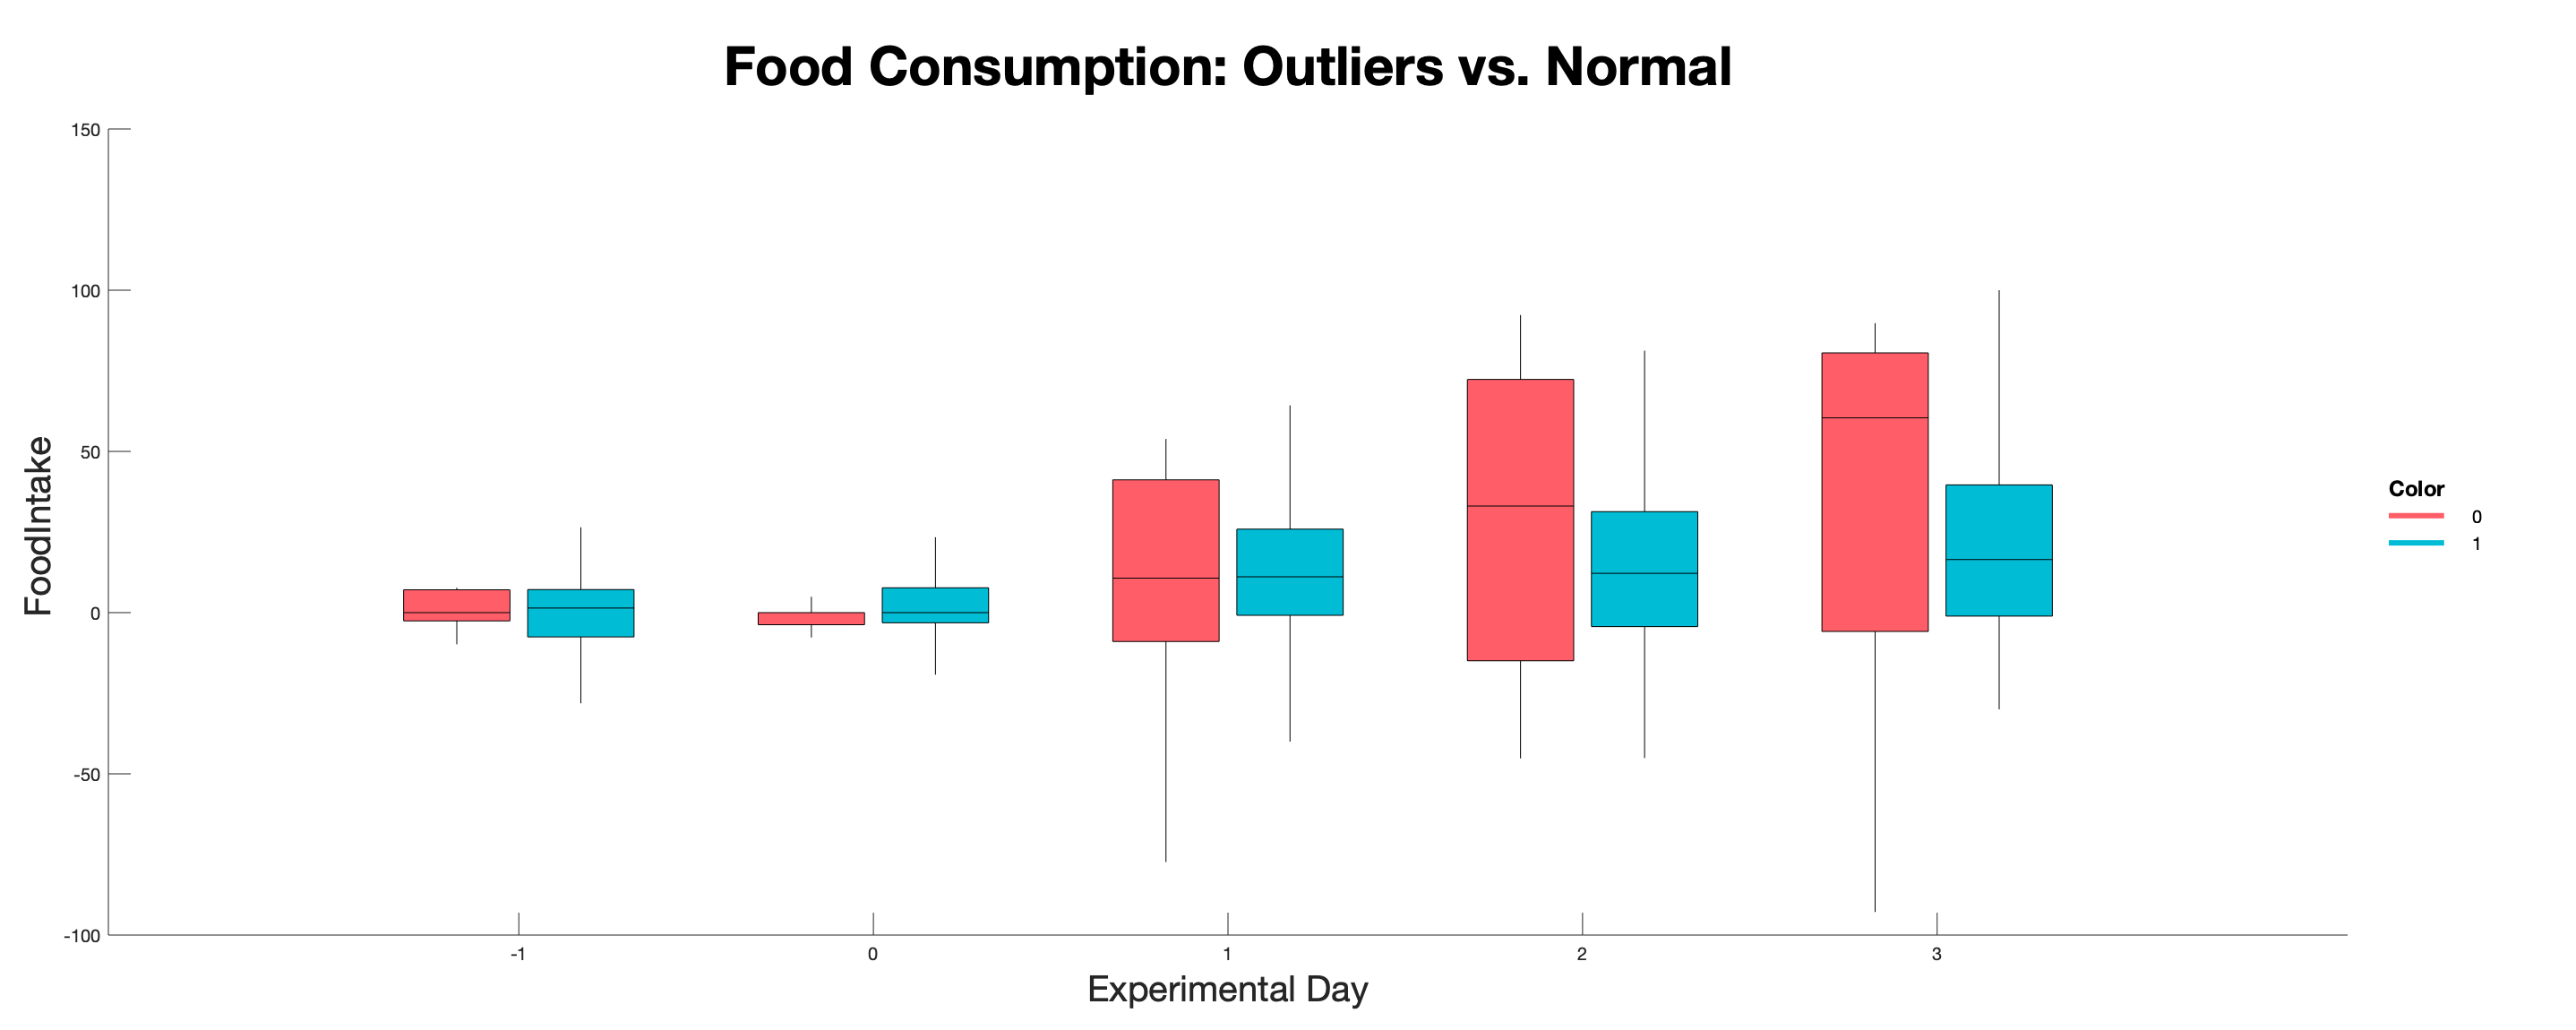

set([c.results.stat_boxplot.outliers_handle],'visible','off')

%More Graphing Fun
c=gramm('x',intakestack.PercentNormIntake,'color',intakestack.Master_ID~="H145" & intakestack.Master_ID~="H223" & intakestack.Master_ID~="H89" & intakestack.Master_ID~="H214" & intakestack.Master_ID~="H19"' ...
    & intakestack.Master_ID~="H117" & intakestack.Master_ID~="H19" & intakestack.Master_ID~="H117"& intakestack.Master_ID~="H205" & intakestack.Master_ID~="H30" & intakestack.Master_ID~="H116"& intakestack.Master_ID~="H123" & intakestack.Master_ID~="H182" & intakestack.Master_ID~="H205"& intakestack.Master_ID~="H120" ...
    & intakestack.Master_ID~="H184" & intakestack.Master_ID~="H199" & intakestack.Master_ID~="H215"& intakestack.Master_ID~="H217"& intakestack.Master_ID~="H219"& intakestack.Master_ID~="H46" & intakestack.Master_ID~="H47"& intakestack.Master_ID~="H200"& intakestack.Master_ID~="H213")

c =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


c.facet_grid([],intakestack.Day)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


c.stat_bin('fill','transparent');
c.set_names('column', 'Day','x','Food Consumption','y','Count')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c.set_title('Food Consumption: Outliers(Red) vs. Normal(Blue)');
figure('Position',[100 100 2000 800]);
c.axe_property('YLim',[0 18])

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


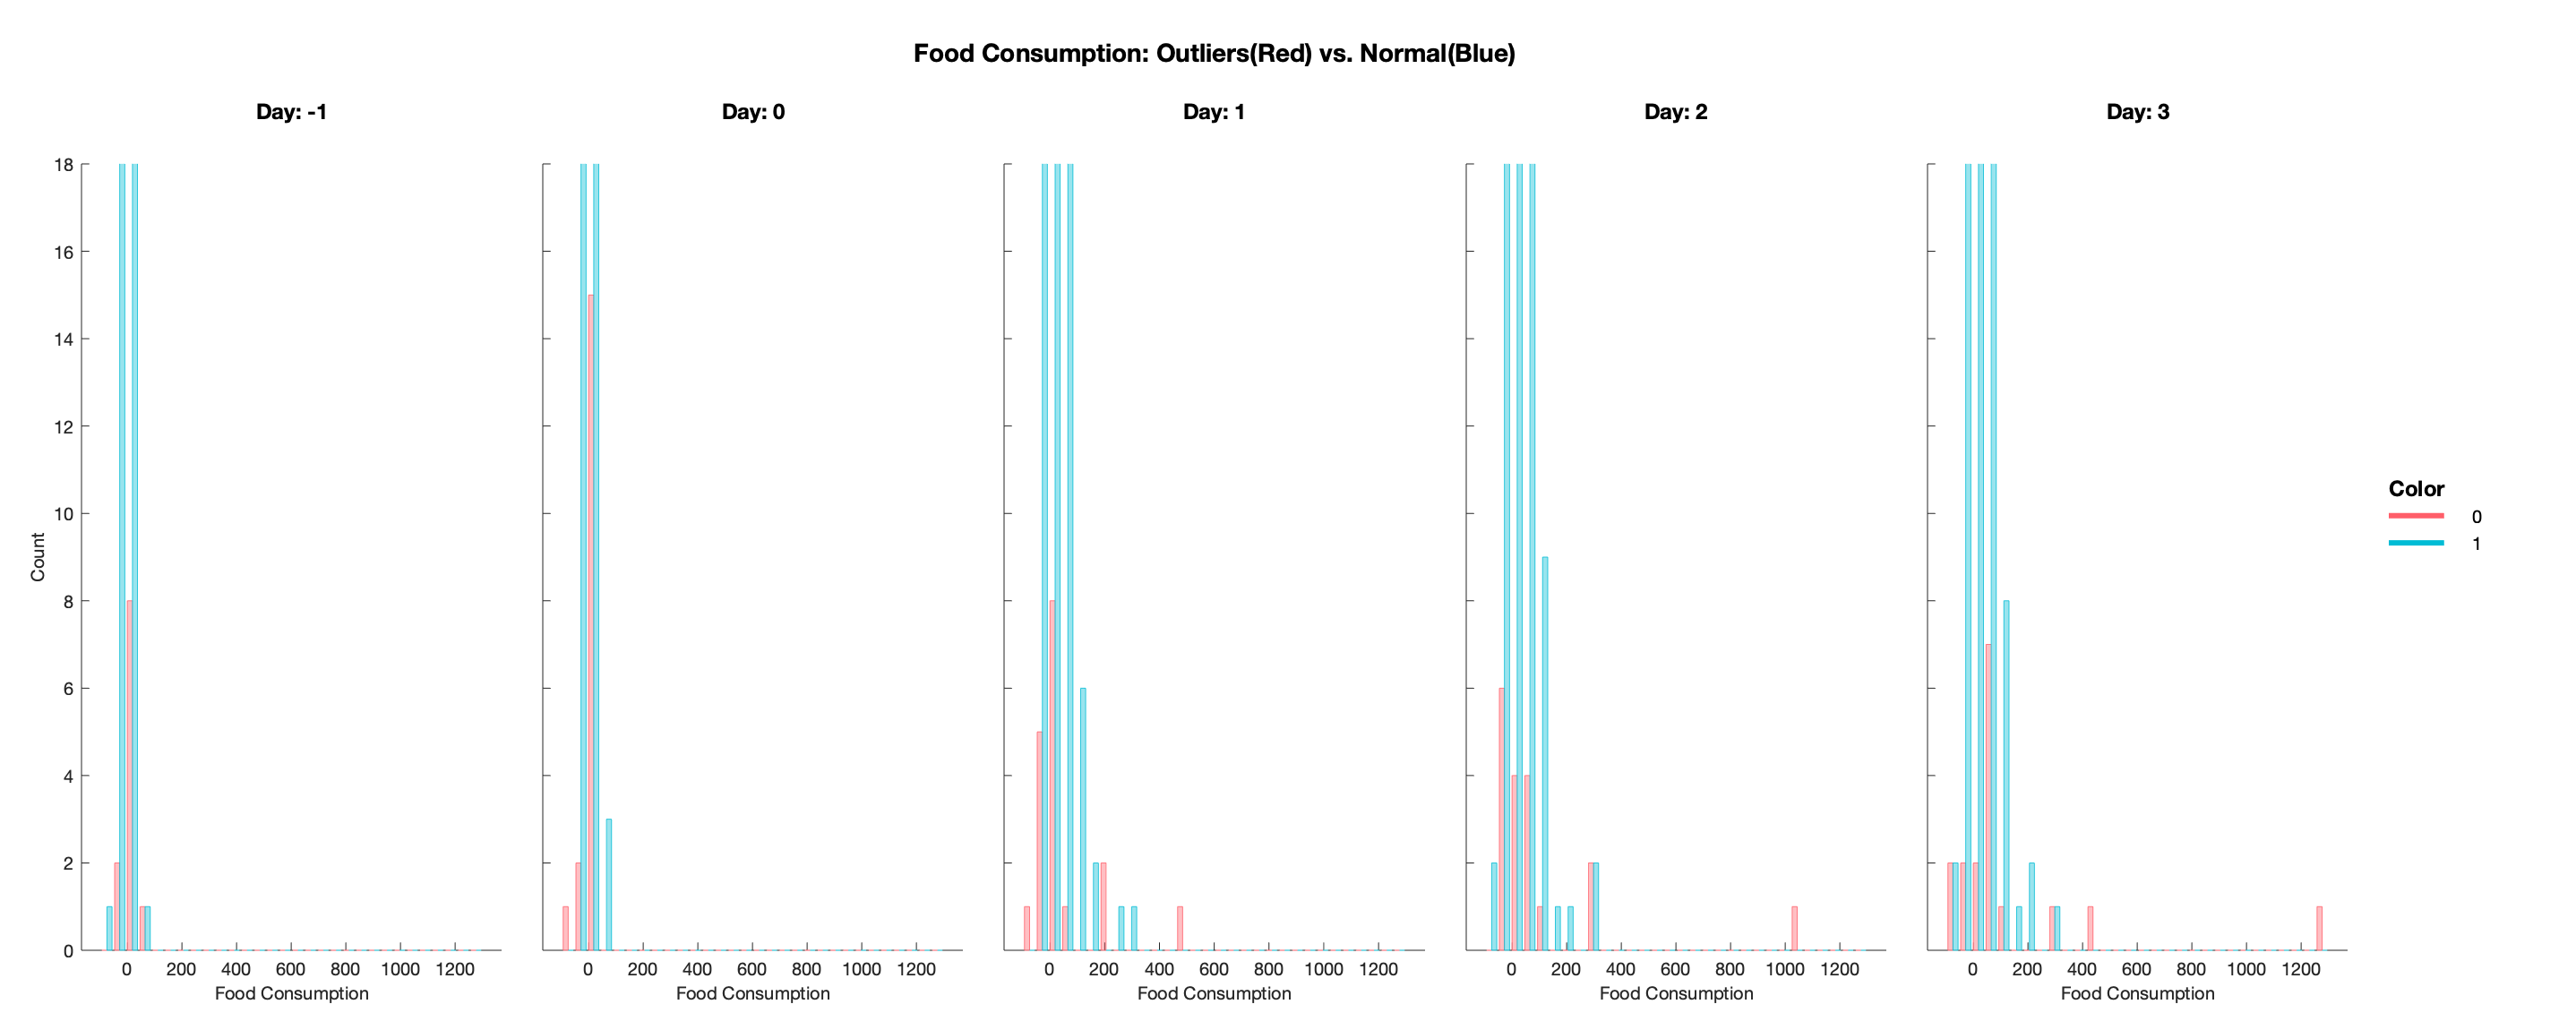

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×5 Axes]
               results: [1×1 struct]


c.draw